clc;
clear;
runtime=120

runtime = 120

for count=1:runtime
Road_length  =100;
car_number   = 20;
acceleration = 2+0.5*count
deceleration =-6.5;
a_d(count)=abs(acceleration/deceleration)
%initial speed
u = 5;
%time limitis
time =1000;
%limit speed
lim = 15;

%repeat loop
for l=1:40
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/2);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
boxave(l,count)=m(l);
end

S(count)=std(m);
averagespeed(count) = mean(m);
maxave(count)=max(m)-averagespeed(count);
minave(count)=averagespeed(count)-min(m);
acc(count)=acceleration;
%percentage
end

acceleration = 2.5000

a_d = 0.3846

acceleration = 3

a_d =     0.3846    0.4615


acceleration = 3.5000

a_d =     0.3846    0.4615    0.5385


acceleration = 4

a_d =     0.3846    0.4615    0.5385    0.6154


acceleration = 4.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923


acceleration = 5

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692


acceleration = 5.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462


acceleration = 6

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231


acceleration = 6.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000


acceleration = 7

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769


acceleration = 7.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538


acceleration = 8

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308


acceleration = 8.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077


acceleration = 9

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846


acceleration = 9.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615


acceleration = 10

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385


acceleration = 10.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154


acceleration = 11

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923


acceleration = 11.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692


acceleration = 12

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462


acceleration = 12.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231


acceleration = 13

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000


acceleration = 13.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769


acceleration = 14

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538


acceleration = 14.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308


acceleration = 15

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077


acceleration = 15.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846


acceleration = 16

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615


acceleration = 16.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385


acceleration = 17

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 17.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923


acceleration = 18

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692


acceleration = 18.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462


acceleration = 19

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231


acceleration = 19.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000


acceleration = 20

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769


acceleration = 20.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538


acceleration = 21

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308


acceleration = 21.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077


acceleration = 22

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846


acceleration = 22.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615


acceleration = 23

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385


acceleration = 23.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154


acceleration = 24

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154    3.6923


acceleration = 24.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154    3.6923    3.7692


acceleration = 25

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154    3.6923    3.7692    3.8462


acceleration = 25.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154    3.6923    3.7692    3.8462    3.9231


acceleration = 26

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154    3.6923    3.7692    3.8462    3.9231    4.0000


acceleration = 26.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154    3.6923    3.7692    3.8462    3.9231    4.0000    4.0769


acceleration = 27

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154    3.6923    3.7692    3.8462    3.9231    4.0000    4.0769    4.1538


acceleration = 27.5000

a_d =     0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154    2.6923    2.7692    2.8462    2.9231    3.0000    3.0769    3.1538    3.2308    3.3077    3.3846    3.4615    3.5385    3.6154    3.6923    3.7692    3.8462    3.9231    4.0000    4.0769    4.1538


acceleration = 28

a_d = 1×52
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 28.5000

a_d = 1×53
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 29

a_d = 1×54
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 29.5000

a_d = 1×55
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 30

a_d = 1×56
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 30.5000

a_d = 1×57
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 31

a_d = 1×58
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 31.5000

a_d = 1×59
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 32

a_d = 1×60
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 32.5000

a_d = 1×61
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 33

a_d = 1×62
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 33.5000

a_d = 1×63
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 34

a_d = 1×64
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 34.5000

a_d = 1×65
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 35

a_d = 1×66
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 35.5000

a_d = 1×67
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 36

a_d = 1×68
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 36.5000

a_d = 1×69
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 37

a_d = 1×70
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 37.5000

a_d = 1×71
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 38

a_d = 1×72
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 38.5000

a_d = 1×73
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 39

a_d = 1×74
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 39.5000

a_d = 1×75
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 40

a_d = 1×76
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 40.5000

a_d = 1×77
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 41

a_d = 1×78
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 41.5000

a_d = 1×79
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 42

a_d = 1×80
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 42.5000

a_d = 1×81
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 43

a_d = 1×82
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 43.5000

a_d = 1×83
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 44

a_d = 1×84
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 44.5000

a_d = 1×85
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 45

a_d = 1×86
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 45.5000

a_d = 1×87
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 46

a_d = 1×88
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 46.5000

a_d = 1×89
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 47

a_d = 1×90
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 47.5000

a_d = 1×91
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 48

a_d = 1×92
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 48.5000

a_d = 1×93
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 49

a_d = 1×94
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 49.5000

a_d = 1×95
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 50

a_d = 1×96
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 50.5000

a_d = 1×97
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 51

a_d = 1×98
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 51.5000

a_d = 1×99
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 52

a_d = 1×100
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 52.5000

a_d = 1×101
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 53

a_d = 1×102
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 53.5000

a_d = 1×103
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 54

a_d = 1×104
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 54.5000

a_d = 1×105
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 55

a_d = 1×106
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 55.5000

a_d = 1×107
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 56

a_d = 1×108
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 56.5000

a_d = 1×109
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 57

a_d = 1×110
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 57.5000

a_d = 1×111
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 58

a_d = 1×112
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 58.5000

a_d = 1×113
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 59

a_d = 1×114
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 59.5000

a_d = 1×115
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 60

a_d = 1×116
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 60.5000

a_d = 1×117
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 61

a_d = 1×118
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 61.5000

a_d = 1×119
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


acceleration = 62

a_d = 1×120
    0.3846    0.4615    0.5385    0.6154    0.6923    0.7692    0.8462    0.9231    1.0000    1.0769    1.1538    1.2308    1.3077    1.3846    1.4615    1.5385    1.6154    1.6923    1.7692    1.8462    1.9231    2.0000    2.0769    2.1538    2.2308    2.3077    2.3846    2.4615    2.5385    2.6154


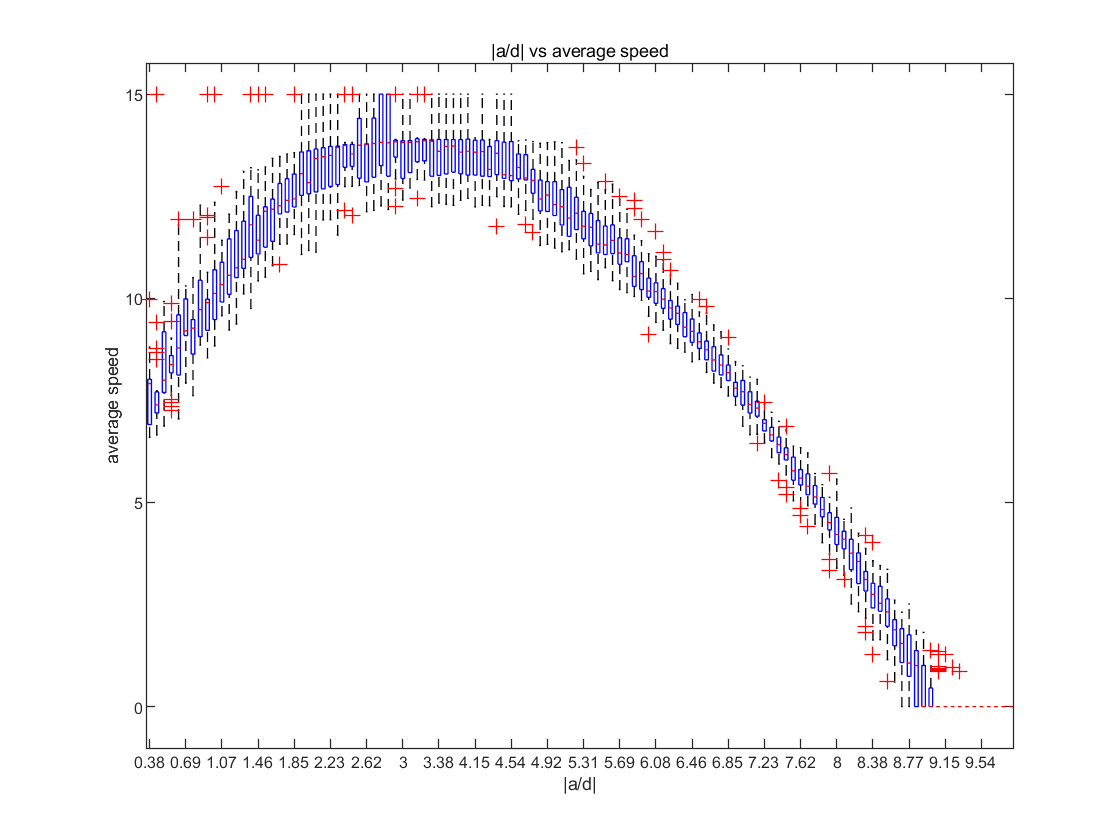

boxplot(boxave,a_d)
set(gca,'Xtick',[1:5:120],'FontSize',6)
set(gca,'Xticklabel',{'0.38','0.69','1.07','1.46','1.85','2.23','2.62','3','3.38','4.15','4.54','4.92','5.31','5.69','6.08','6.46','6.85','7.23','7.62','8','8.38','8.77','9.15','9.54'})
title("|a/d| vs average speed") 
xlabel('|a/d|')
ylabel('average speed')

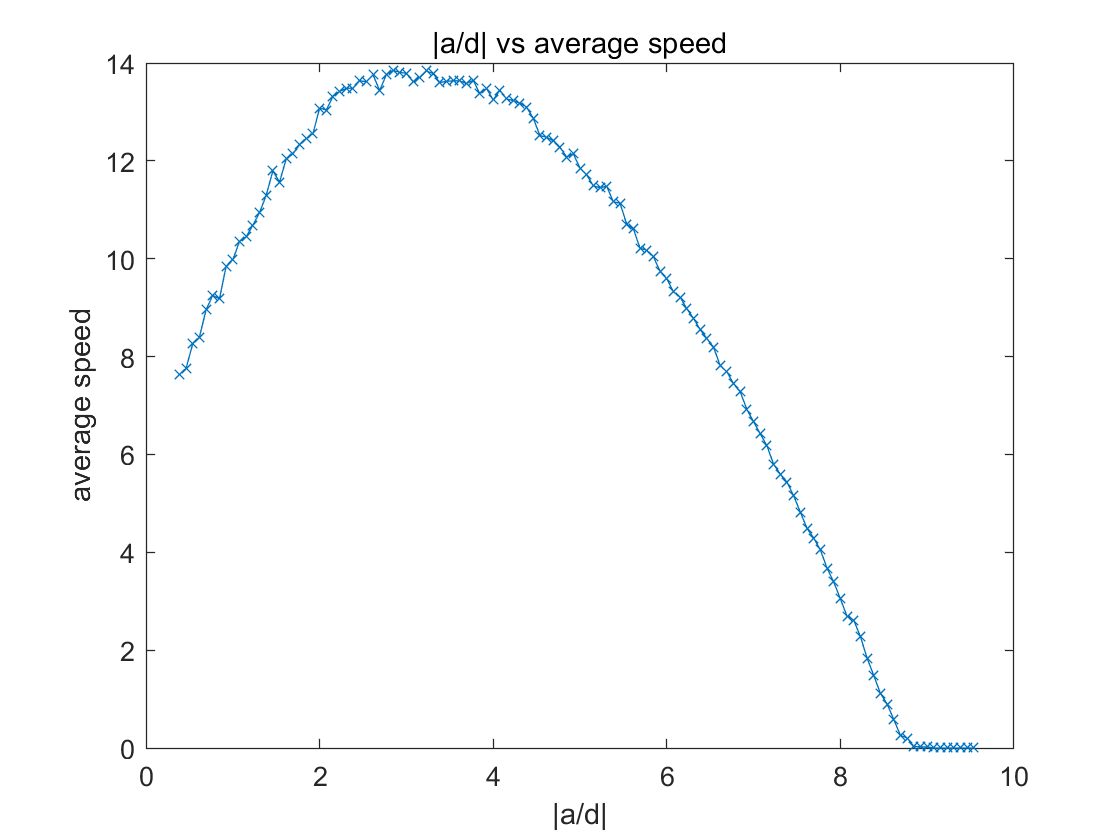


plot(a_d,averagespeed,"-x","MarkerSize",5)
title("|a/d| vs average speed") 
xlabel('|a/d|')
ylabel('average speed')

%xticks([10 20 30 40 50 60 70 80])
%xticklabels({'0.030','0.040','0.050','0.060','0.070','0.080','0.090','0.1'})
